# **Script 4 (S4)**

Create a script that allows you to visualize a uniform distribution for a linear charge density. Make the representation for 3 spatial geometric regions that allow you to draw conclusions about the shape of the field.

## **The first thing we can do is initialize the common variables for all cases**

clear; clc
lambda = 1e-3;           % Linear charge density [C/m]
pini = [-.05 0 0];       % Initial point [m]
pfin = [.05 0 0];        % End point of the line [m]
N = 100+1;               % Number of elements to discretize
linea = pini + linspace(0,1,N)'.*(pfin-pini);
dl = norm(pfin-pini)/N;  % Spatial resolution of each element, delta l
dq = lambda*dl;          % incremental charge
Nquiv = 50+1;            % We are going to create a spatial grid with Nquiv points in which we evaluate the field
d = 0.001;               % Distance to which we place the representation planes

## Now, we create the scenario. This part can often be the most complex. Either way, this part is very IMPORTANT!

caso = 2;     % WE CHOOSE HERE ONE OF THE THREE SPATIAL GEOMETRIC REGIONS
switch caso
    case 1 % Plane parallel to the line
        x = linspace(-.1,.1,Nquiv);
        y = linspace(-.05,.05,Nquiv);
        [X,Y] = meshgrid(x,y);
        Z = d*ones(size(Y));
        x=X(:); y=Y(:); z=Z(:);
    case 2 % Plane perpendicular to the line
        z = linspace(-.05,.05,Nquiv);
        y = linspace(-.05,.05,Nquiv);
        [Y,Z] = meshgrid(y,z);
        X = (d+.05)*ones(size(Y));
        x=X(:); y=Y(:); z=Z(:);
    case 3 % Circle concentric to the line
        angulo = linspace(0,2*pi,2*Nquiv);
        radio = .06;          % If we test with R less than the length of the line, what happens?
        nn = zeros(size(angulo));
        for i=1:length(angulo)
            nn(i) = radio * exp(1i*angulo(i));
        end
        x = real(nn)'; y = imag(nn)'; z = 0*ones(size(y));
end
R = [x y z];

## Perfect, we have everything ready to calculate the electric field in the R plane

Et = zeros(size(R));
for i=1:N % Each position of the line
    for ir=1:size(R,1) % Each position of the plane (cases 1 and 2) or circle (case 3)
        E(ir,:)=electricField(linea(i,:),R(ir,:),dq);
    end
    Et = Et + E;
end

## Last but not least, let's visualize the results. In this case, the obtained field.

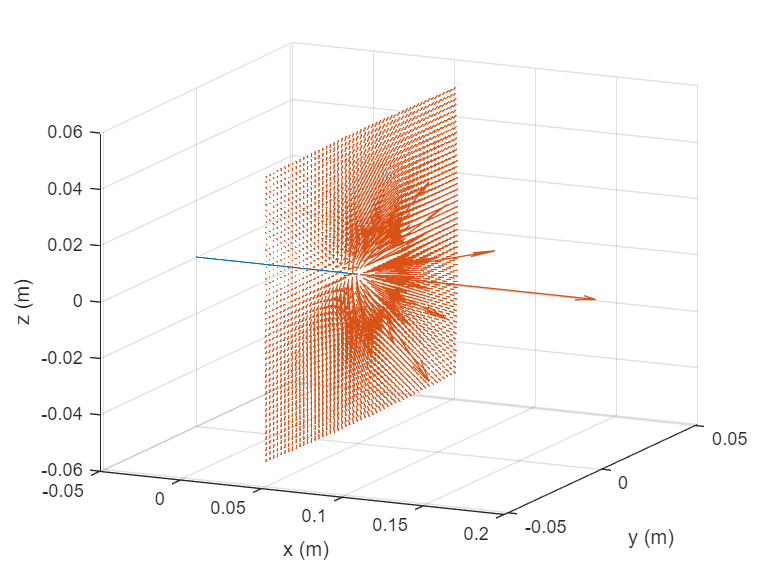

s = 1e11;   % Normalization to be able to see with quiver
Et = Et/s;
figure(1)
plot3(linea(:,1),linea(:,2),linea(:,3)); hold on
quiver3(x,y,z,Et(:,1),Et(:,2),Et(:,3),0);
xlabel('x (m)'), ylabel('y (m)'), zlabel('z (m)'), grid on, hold off, rotate3d on

# Let's leave here the functions that we need and that we have already used in the previous scripts

function E=electricField(ri,rt,qi)
c=299792458; % Speed of light (m/s)
ke=c^2/1e7;  % Coulomb constant (Nm^2/C^2)
r = norm(rt-ri);  % Distance in the direction ri to rt
u = (rt-ri)/r; % Unitary vector of distance in Cartesian coordinates
E = ke*qi/r^2 * u; % Electric field (E)
end